# 11. ウェーブレットしきい値処理によるノイズ除去

clear;
clf;
getd = @(p)path(p,path);
getd('toolbox_signal/');
getd('toolbox_general/');
rng('default');

## ハードしきい値処理によるノイズ除去

前回は空間領域での線形フィルタを適用することで，画像のノイズ除去を行った．今回は，周波数領域（変換領域）でのノイズ除去を考えてみよう．

ウェーブレット変換のような「自然画像をスパースに表現する変換（一部の係数が大きい絶対値を持ち、その他の大多数の係数はゼロ or ゼロに近い値を持つ）」を利用することで，シンプルかつ効果的なノイズ除去が実現できる．

**ハードしきい値処理**（硬閾値処理，Hard-Thresholding, HT）によるノイズ除去では，ノイズを含む観測画像にウェーブレット変換を施し，ウェーブレット変換係数に対して「しきい値 $T>0$ 以下の絶対値を持つ係数をゼロにする処理」を施した後，逆ウェーブレット変換することでノイズ除去画像を得る．これは，小さい絶対値の変換係数では，ノイズのエネルギーが原画像のそれより高いと仮定していることに相当する．

※ 逆に言えば，大きい絶対値を持つ係数は原画像由来だと考えていることになる．

HT処理は以下のような関数として表現できる．入力ベクトル $\mathbf{x} = [x_1, \dots, x_N]^\top$ に対して，


$$[\mathrm{HT}(\mathbf{x}, T)]_i = \begin{cases} 0 & \mbox{if } -T \leq x_i \leq T\\ x_i & \mbox{otherwise}\end{cases}$$


画像を読み込みガウス性ノイズを付加する．

name = 'house';
u = load_image(name,[]);
u = u/255; % 画素値を [0,1] に正規化
n = length(u);
N = n^2;

sigma = 0.1;
v = u + randn(n,n)*sigma;

任意のしきい値を定め，HT関数を記述し可視化する．横軸が入力係数の値，縦軸が出力係数の値に対応する．

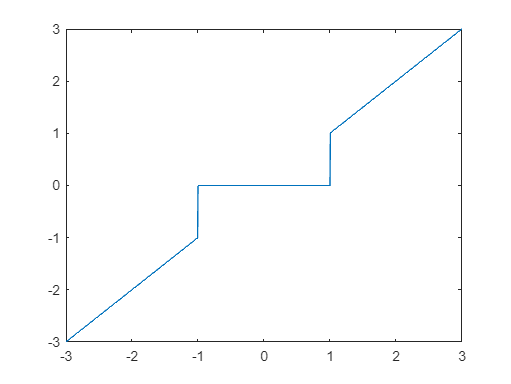

T = 1; % しきい値
alpha = linspace(-3,3,1000);
HT = @(z,a) z.*(abs(z)>a);
alphaT = HT(alpha,T);

figure;
plot(alpha, alphaT); % HT関数の可視化
axis tight;

実際に画像に対しノイズ除去を行ってみよう．まず，ノイズを含む観測画像のウェーブレット係数を計算する．

options.ti = 0; % 直交ウェーブレット
Jmin = 4; % 最小スケール
vw = perform_wavelet_transf(v,Jmin,+1,options); % ウェーブレット変換を施す関数

観測画像のウェーブレット係数を表示する．

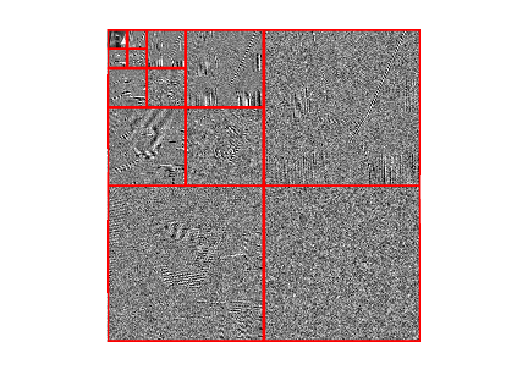

figure;
plot_wavelet(vw,Jmin);

しきい値を定め（一般にはノイズの強度（分散）に比例するように決めるとよい），HTする．

T = 3*sigma;
vwT = vw .* (abs(vw)>T);

HTされた係数を表示する．見て分かる通り，小さい係数がすべて0（灰色）になる．

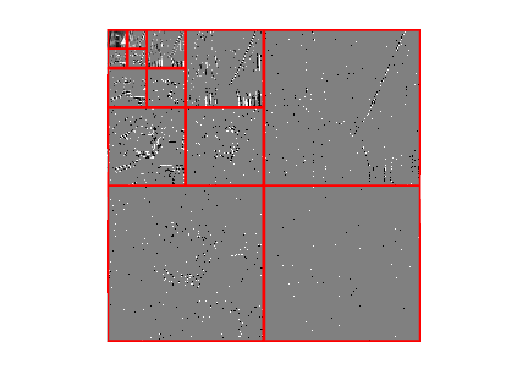

figure;
plot_wavelet(vwT,Jmin);

HTされた係数に逆ウェーブレット変換を施し画像を再構成することで，ノイズを除去した復元画像を得る．

uHT = perform_wavelet_transf(vwT,Jmin,-1,options); % 第3引数 -1 は逆変換を意味する

復元画像を表示する．0でない係数はかなり少ないが，よく原画像を推定できていることがわかる．

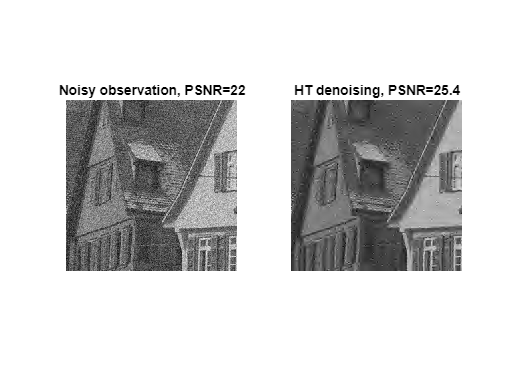

figure;
imageplot(v, strcat(['Noisy observation, PSNR=' num2str(psnr(u,v),3)]), 1, 2, 1);
imageplot(uHT, strcat(['HT denoising, PSNR=' num2str(psnr(u,uHT),3)]), 1, 2, 2);

## ソフトしきい値処理によるノイズ除去

HTによるノイズ除去結果には，ウェーブレット基底に似たアーティファクト（視覚的に望ましくない人工的に生成された成分）が生じる．これを緩和するには**ソフトしきい値処理**（軟閾値処理，Soft-Thresholding, ST）が有効である．

ST関数は以下のように表現できる．入力ベクトル $\mathbf{x} = [x_1, \dots, x_N]^\top$ に対して，


$$[\mathrm{ST}(\mathbf{x}, T)]_i = \mathrm{sign}(x_i)\max(|x_{i}| - T, 0)$$


ここで，$\mathrm{sign}$ は符号関数（引数が非負の場合は1，負の場合は−1を返す関数）を表す．STは全ての係数の絶対値をT小さくすることに相当する（T以下の絶対値を持つ係数は $0$ にする）．

しきい値を定め，ST関数を記述し可視化する．横軸が入力係数の値，縦軸が出力係数の値に対応する．

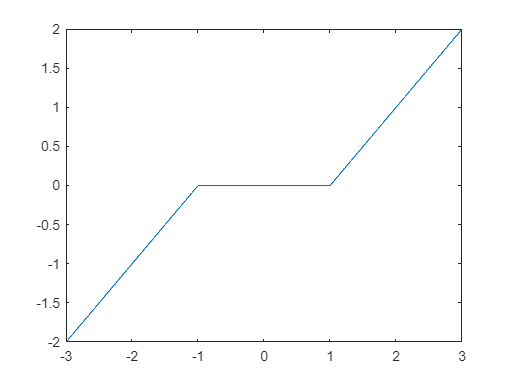

T = 1;
alpha = linspace(-3,3,1000);
ST = @(z,a) sign(z).*max(abs(z)-a, 0);
alphaT = ST(alpha,T);

figure;
plot(alpha, alphaT);
axis tight;

しきい値を定め，観測画像のウェーブレット係数をSTする．

T = sigma;
vwT = ST(vw,T);

ノイズ除去性能をより向上させるためには，近似係数（最低周波数に対応する係数＝左上の係数）はSTしない方がよい．これは，近似係数が画像の大域的な成分に対応しており，近似係数を操作すると画像全体としてのエネルギー（＝輝度の平均値）が低下してしまうためである．加えて，ハードしきい値処理でも述べたように，詳細係数部分（＝高周波数成分）では原画像のエネルギーよりノイズのエネルギーの方が支配的であるため，これらの係数をSTするだけで事足りる．

vwT(1:2^Jmin,1:2^Jmin) = vw(1:2^Jmin,1:2^Jmin); % 近似係数部分にST前の係数を上書き

STされた係数を表示する．

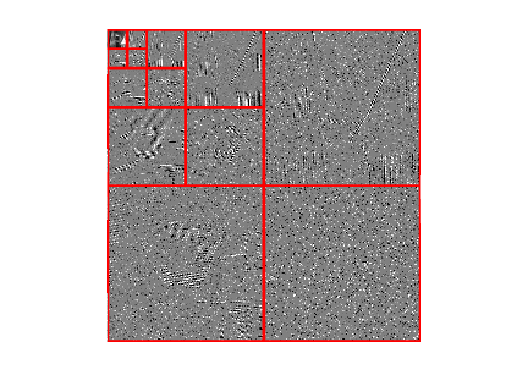

figure;
plot_wavelet(vwT,Jmin);

STされた係数に逆ウェーブレット変換を施し画像を再構成することで，ノイズを除去した復元画像を得る．

uST = perform_wavelet_transf(vwT,Jmin,-1,options);

復元画像を表示する．

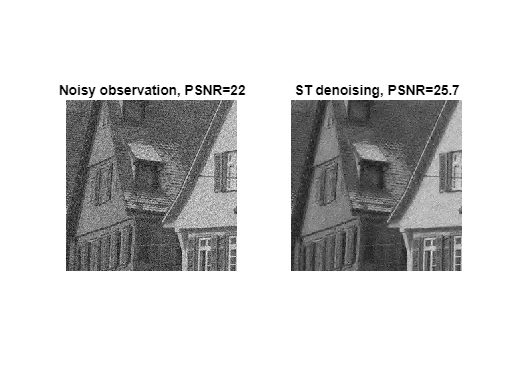

figure;
imageplot(v, ['Noisy observation, PSNR=' num2str(psnr(u,v),3)], 1, 2, 1);
imageplot(uST, ['ST denoising, PSNR=' num2str(psnr(u,uST),3)], 1, 2, 2);

## **演習問題**

**演習11-1**: グレースケール画像'house'を読み込み， $\sigma=0.1$ のガウス性ノイズを付加した観測画像を生成する．その上で，直交ウェーブレット変換（$Jmin = 4$ に設定せよ）を利用したソフトしきい値処理によるノイズ除去について．

- 横軸を $\tau = T/\sigma$ （しきい値をノイズの標準偏差で正規化した値）とし， $[0.5, 2]$ の範囲で $0.1$ 刻みに $\tau$ を変化させながら復元画像 $\mathbf{u}_r$ を求め，縦軸に $\tau$ の関数として復元誤差 $\|\mathbf{u}_r-\mathbf{u}\|$ をプロットせよ．

- $\tau$ を変化させた際に復元誤差が最小となるような最適な $\tau$ を求め，対応する復元画像（最適な $\tau$ の値と原画像とのPSNR [dB] も示すこと）を原画像と観測画像も含めて $2\times2$ のグリッドに表示せよ（上段：原画像と観測画像、下段：直交ウェーブレットによる復元画像）．

ただし，近似係数はしきい値処理せず維持すること．

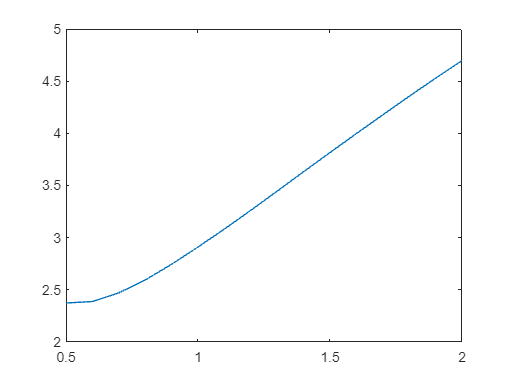

figure;
name = 'house';
u = load_image(name,[]);
u = u/255; % 画素値を [0,1] に正規化
n = length(u);
N = n^2;

sigma = 0.1;
v = u + randn(n,n)*sigma;

options.ti = 0; % 直交ウェーブレット
Jmin = 4; % 最小スケール
vw = perform_wavelet_transf(v,Jmin,+1,options); % ウェーブレット変換を施す関数

tau_list = 0.5:0.1:2;
tau_length = length(tau_list);
error = [];

for i = 1:tau_length
    T = sigma*tau_list(i);
    vwT = ST(vw,T);
    vwT(1:2^Jmin,1:2^Jmin) = vw(1:2^Jmin,1:2^Jmin);
    uST = perform_wavelet_transf(vwT,Jmin,-1,options);

    error(end+1) = sum(norm(uST - u));
end
plot(tau_list, error);

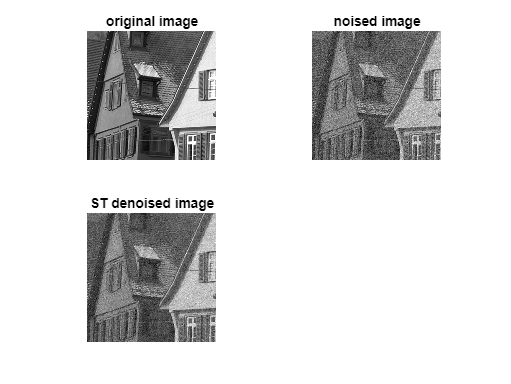



figure;
[min_error ,min_index] = min(error);

T = sigma*tau_list(min_index);
vwT = ST(vw,T);
vwT(1:2^Jmin,1:2^Jmin) = vw(1:2^Jmin,1:2^Jmin);
uST = perform_wavelet_transf(vwT,Jmin,-1,options);

subplot(2,2,1);
imageplot(u, 'original image');
subplot(2,2,2);
imageplot(v, 'noised image');
subplot(2,2,3);
imageplot(uST, 'ST denoised image');


disp(psnr(u,uST));

   23.8864



disp(tau_list(min_index));

    0.5000

